clear
tspan = [0 100];

%平衡点を設定
%{

安定　条件clear
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];

安定じゃない
steady_delta = [-0.2607;0.6415;0.4656];
steady_deltaomega = [0;0;0];
steady_E = [4.3303;3.2225;2.2370];

ぎり安定
steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

不安定
steady_delta = [0.942478;0;-1.41372];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

めちゃ安定?
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

%===================================
%同じ平衡点で、初期値を変えたとき
%もう大丈夫

% Good
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
c
% Not Bad
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;-0.5;0];

*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0.1;-0.1;-0.1];

% Bad
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;0;0];

% Too Bad
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0.5;0;0];
%====================================

% 逆位相により振動が打ち消されて単調減少になっている様子が見やすい
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0.01;0;0;0.1;-0.1;-0.1];

% W_F と W_G が重なってて、逆位相により振動が打ち消されて単調減少になっている様子が見やすい
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0.01;0;0.5;0;0];

% Δω に 0.1 くらいの初期値を入れると崩れる。Δω が許される誤差の大きさは 0.2/50 = 0.004 くらいまで。

%}

% Ured_G, W_F, Wred_G, W_F + Wred_G のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum = 1;
% diff( W_F + Wred_G ) のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum_diff = 1;


steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0;0.1;0;0;0.001;0;0;0];



steady_generator_state = [steady_delta; steady_deltaomega; steady_E];
initial_generator_state = steady_generator_state + error;

judge_steady(initial_generator_state)

線形システムの漸近安定性
Matrix: psi is not steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
受動送電条件(ⅰ),(ⅲ)
Matrix: A is steady.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive semi-definite


judge_steady(steady_generator_state)

線形システムの漸近安定性
Matrix: psi is steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
受動送電条件(ⅰ),(ⅲ)
Matrix: A is steady.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive definite.


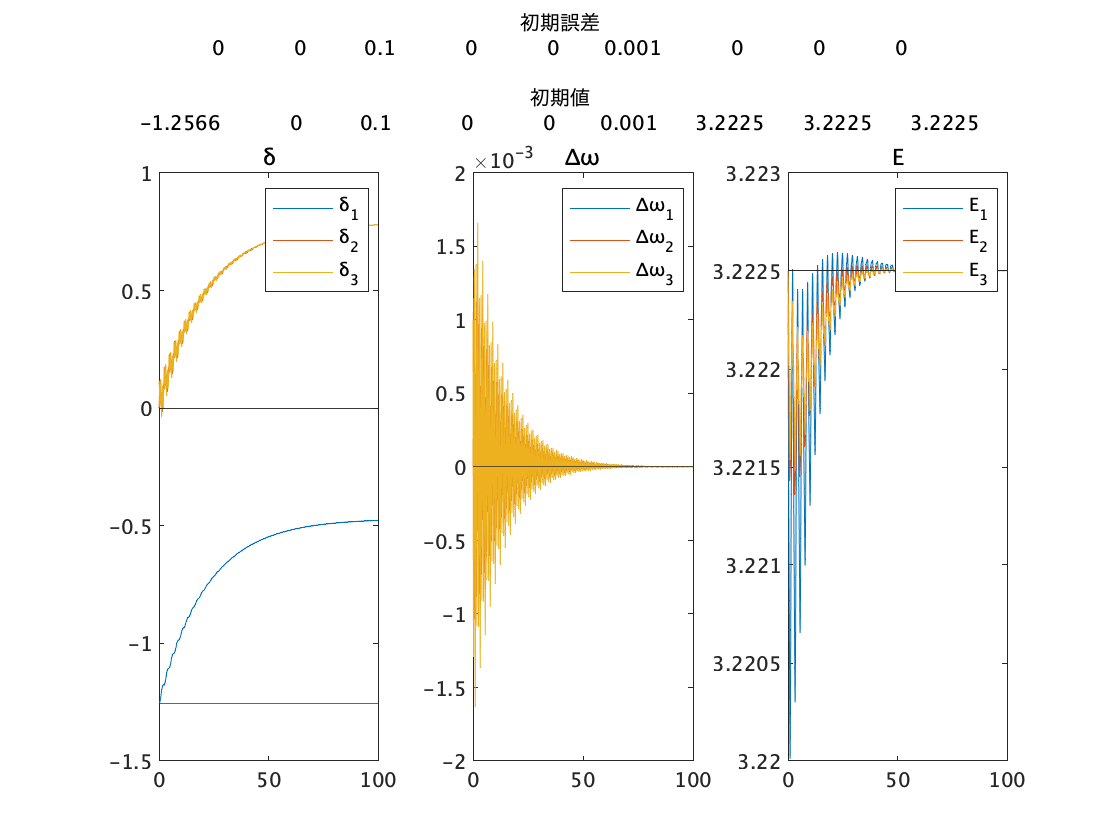

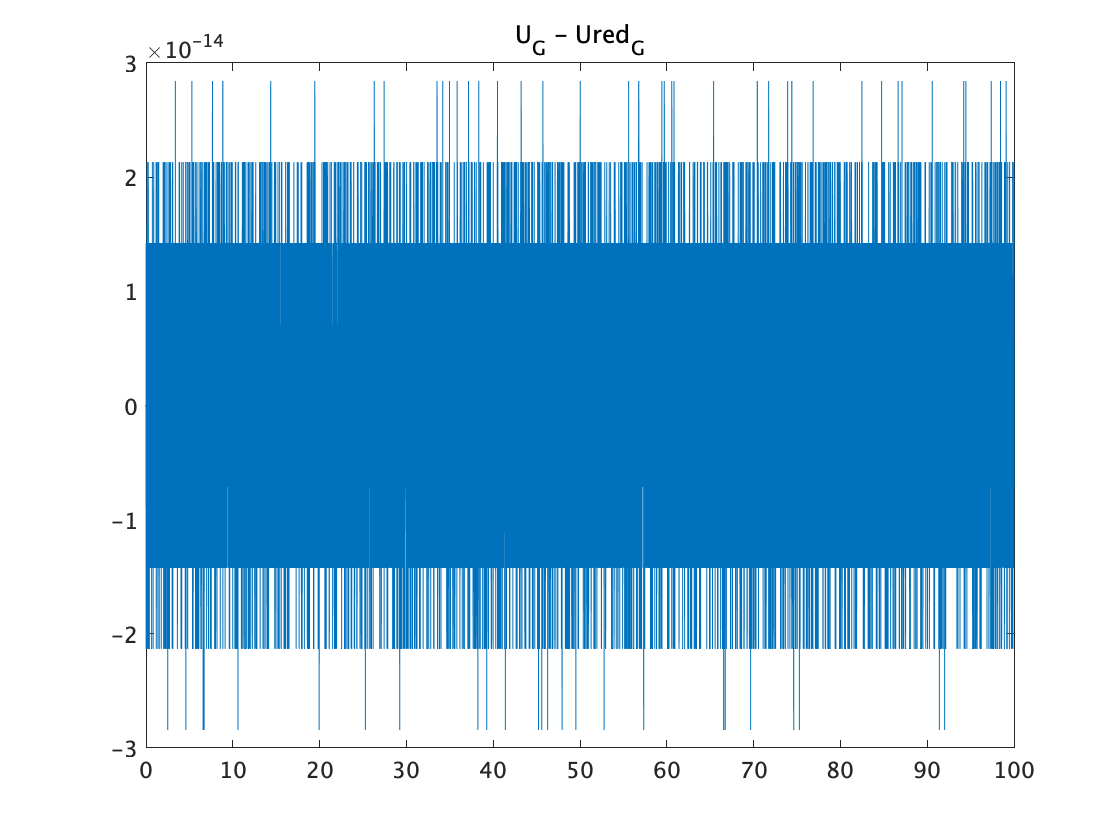

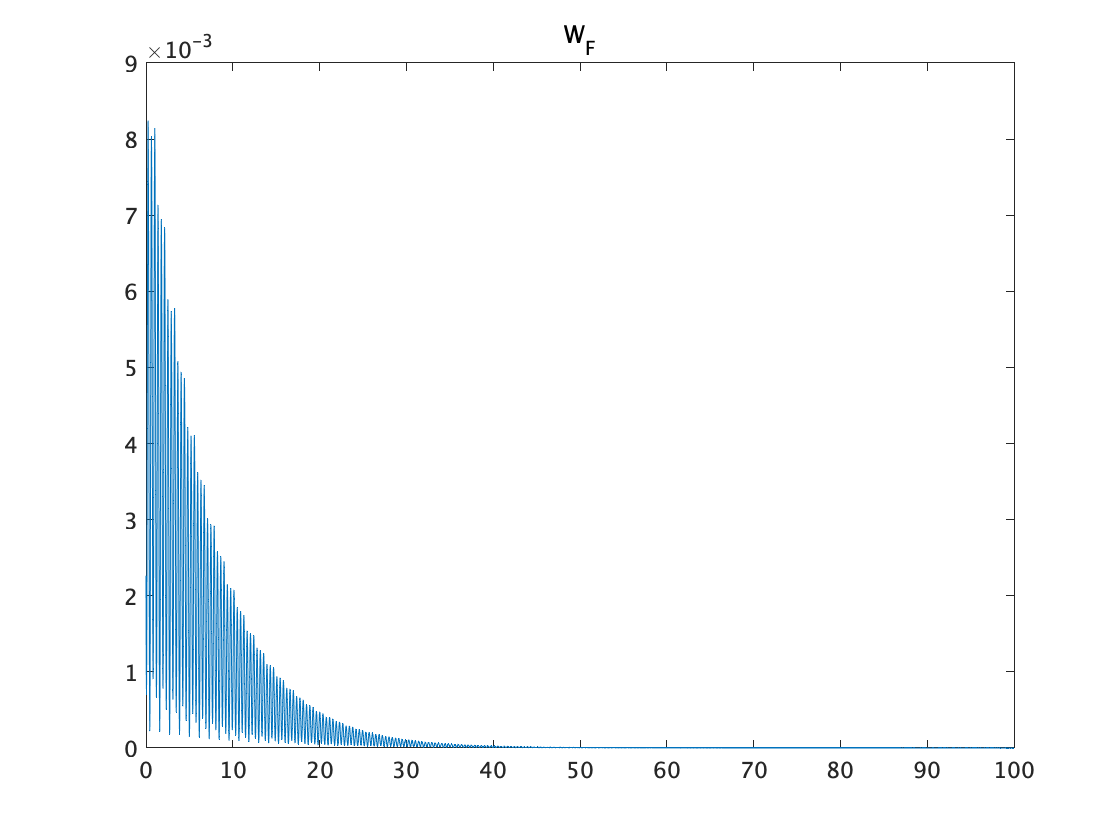

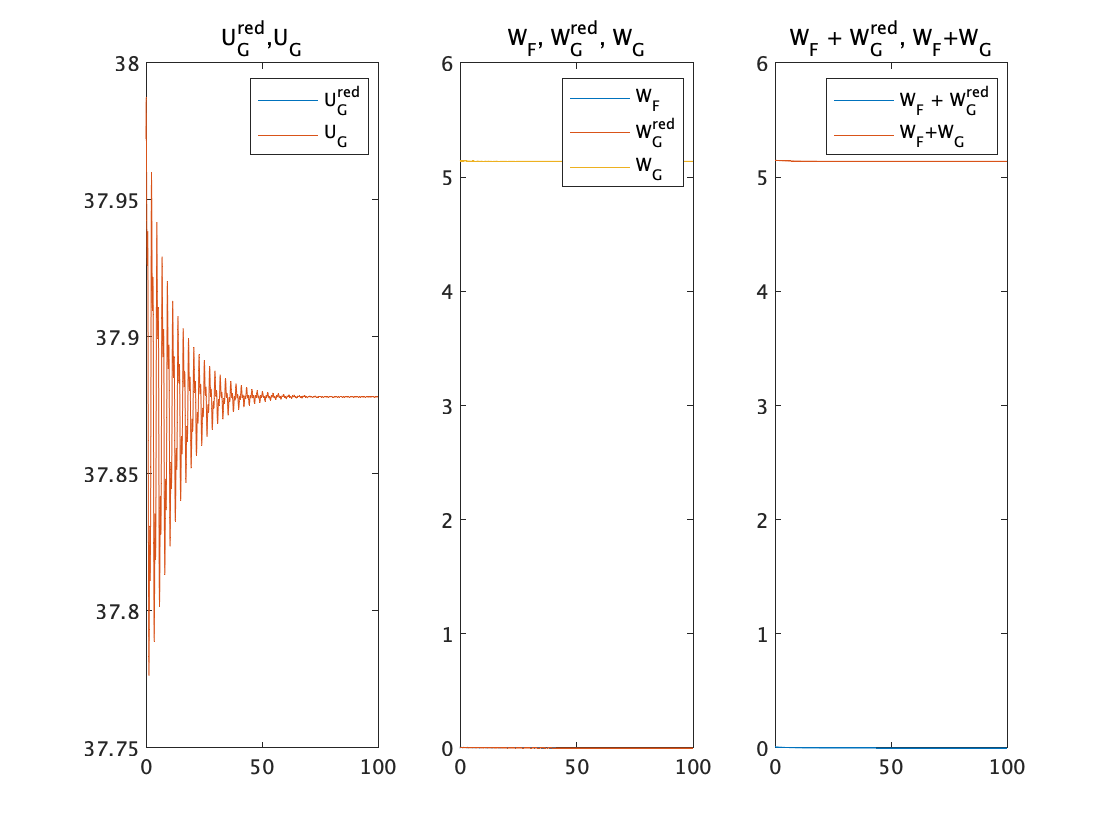

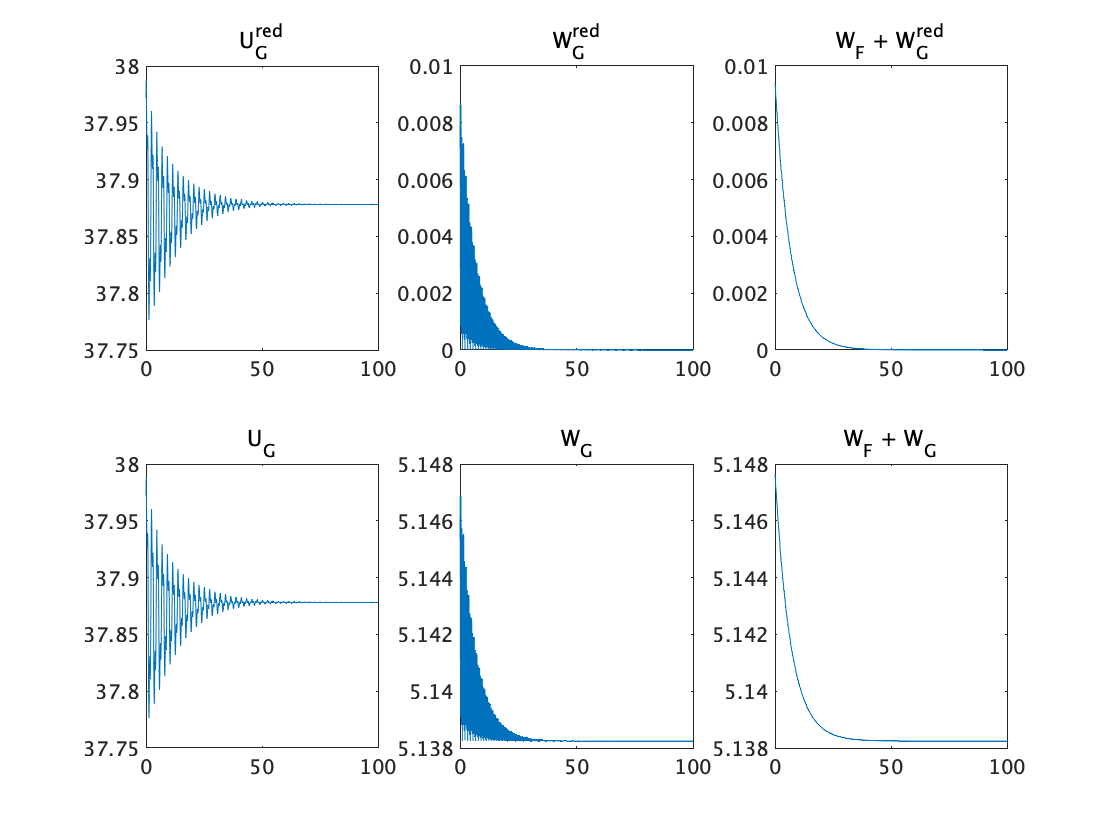

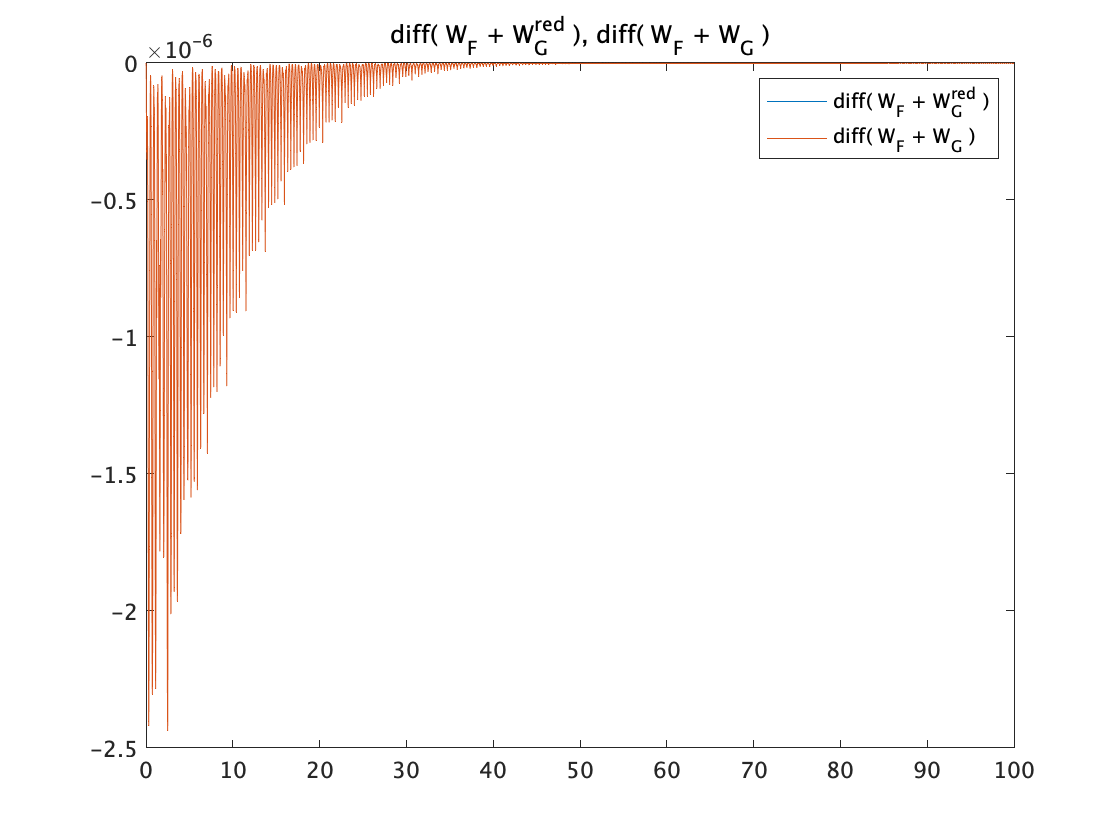

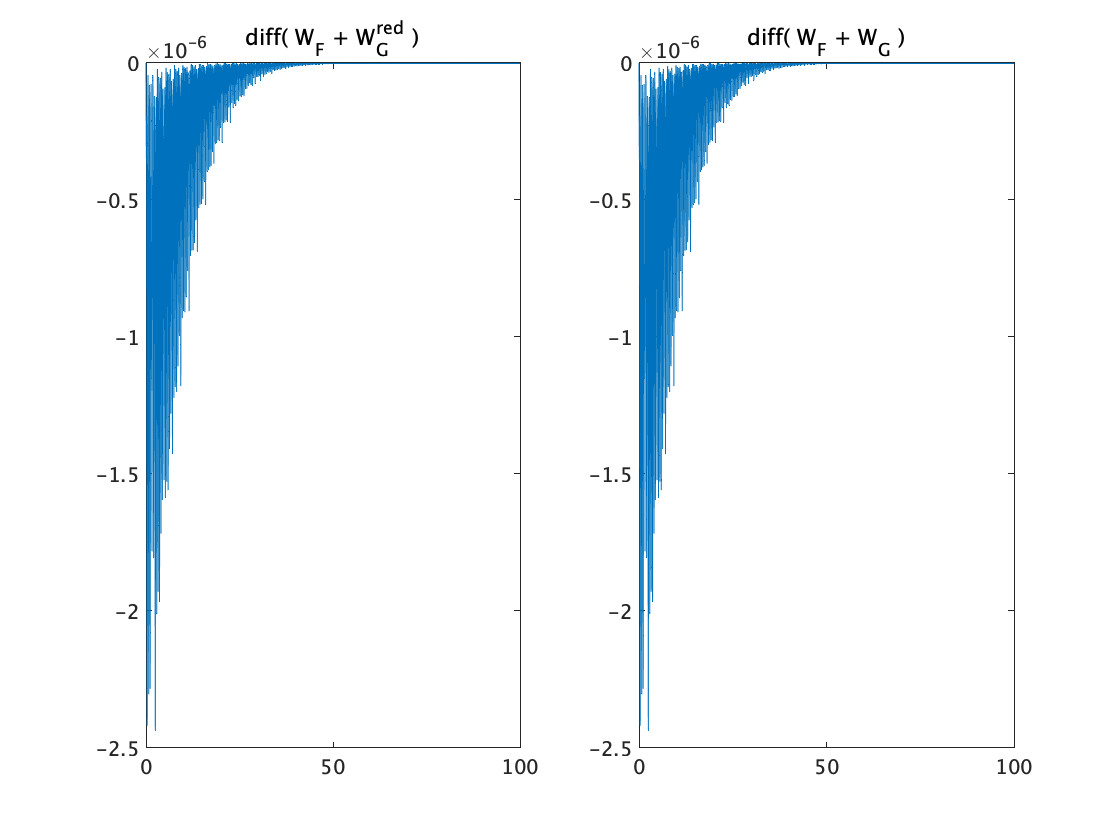

max_diff_W_FGred = -1.7175e-14

max_diff_W_FG = -2.0428e-14


plot_generator_state_wrap = @(error,initial_generator_state) plot_generator_state(error,tspan,initial_generator_state,steady_generator_state,flag_accum,flag_accum_diff);

figure;
plot_generator_state_wrap(error,initial_generator_state);